clc; clear; close;
% column-stochastic weight matrix
B = [1/3  0   0  1/2  0;
     1/3 1/3  0   0   0;
     1/3 1/3 1/2  0  1/3;
      0   0   0  1/2 1/3;
      0  1/3 1/2  0  1/3];

n = length(B);
x = [-1 0 1 2 3]';
v = ones(n,1);
y = zeros(n,1); 
y0 = y;
z = v./x; ADDOPT_z = z;
x0 = x;
alpha = [2 4 5 3 1]';
gradientEstimator = zeros(n,1);
for i=1:n
    y0(i)=compute_gradient(x0(i),x0(i),alpha(i));
end
gradientEstimator_arxiv=y0;

% consensus value
average_x = mean(x);
optimal_x = sum(alpha.*x)/sum(alpha)

optimal_x = 0.8000

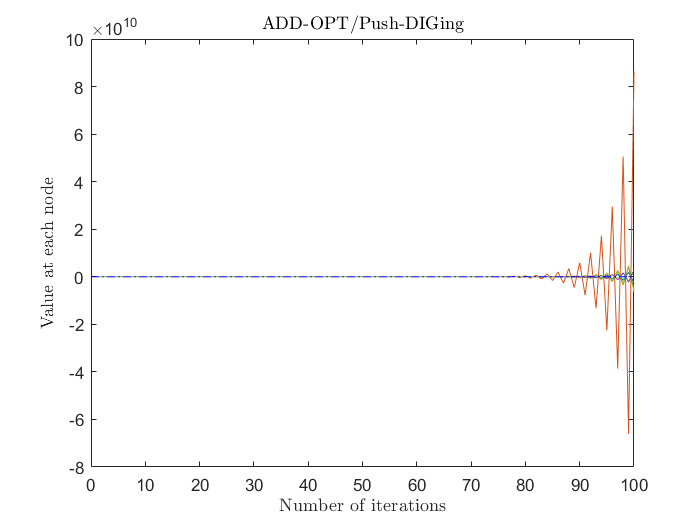

% ADD_OPT/Push-DIGing
    itr = 100; step = 0.1;
    for i=1:itr
        v = B*v;
        x = B*x - step*y;
        z = x./v; 
        ADDOPT_z=[ADDOPT_z z];
        for j=1:n
            gradientEstimator(j)=compute_gradient(z(j),x0(j),alpha(j));
        end
        y = B*y+gradientEstimator-gradientEstimator_arxiv(:,end);
        gradientEstimator_arxiv=[gradientEstimator_arxiv gradientEstimator];
    end

% Plots
   figure; hold on; box on;
   plot(0:itr,ADDOPT_z); title('ADD-OPT/Push-DIGing'); 
   xlabel('Number of iterations'); ylabel('Value at each node');
   plot([0,itr],[optimal_x,optimal_x], 'r-.')
   plot([0,itr],[average_x,average_x], 'b-.')

   
   % Display optimal_x and final z
   fprintf('\nADD_OPT/Push-DIGing Consensus result\n');


ADD_OPT/Push-DIGing Consensus result


   display(z);

z = 	1.0e+10 *

   -0.2436
    8.6403
   -0.6266
    0.2922
   -0.5303
